%% Computer Lab 2 Chapter 2 #: 1, 2, 3, 5b, 5d, 6b, 6d, 9
%The "Example 1", "Example 2", and "Example 3" referred to in #1,2,3 are on pp. 115-118 of the textbook.  
% On #6, you may use RK4 or ode45 and choose three initial conditions of your choice.  On #9, print out a table 
% (as shown in the class lecture on 2.5 Numerical Methods) that compares the outputs; 
% you must use Euler.m and RK4.m that you wrote for the previous problems.


%% Chapter 2 problems
fprintf('Chapter 2 \n')

Chapter 2 


## 1


fprintf('Problem 1 \n')

Problem 1 


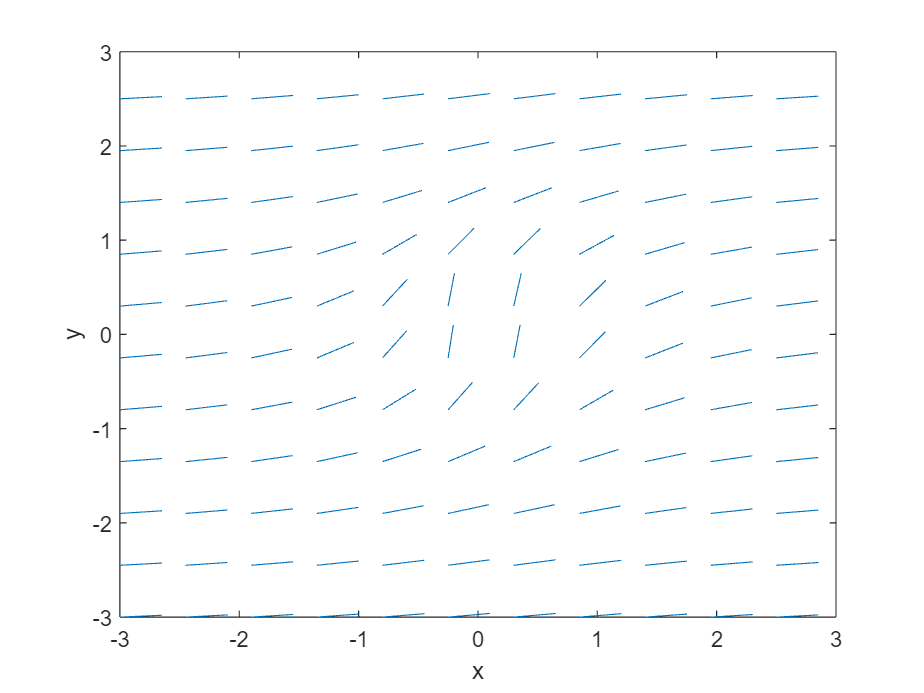

clear all;
[X,Y]=meshgrid(-3:.55:3,-3:.55:3); %Note the CAPITAL letters
DY=1./(X.^2+Y.^2); %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2); %the length of each vector
quiver(X,Y,DX./DW,DY./DW,.5,'.'); %plots normalized vectors
xlabel('x');
ylabel('y');

## 2


fprintf('Problem 2 \n')

Problem 2 


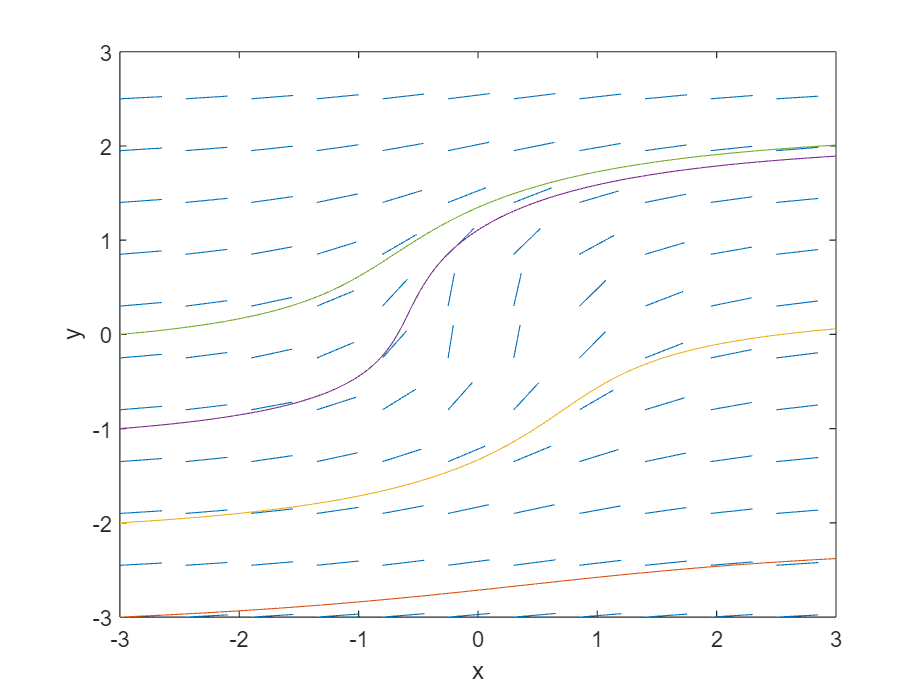

x0=-3; xf=3; y0=-3;
options=odeset('refine',10,'AbsTol',1e-15);
[x,y]=ode45(@Ch2Example,[x0,xf],y0,options);
x0=-3; xf=3; y0=-2;
[x1,y1]=ode45(@Ch2Example,[x0,xf],y0,options);
x0=-3; xf=3; y0=-1;
[x2,y2]=ode45(@Ch2Example,[x0,xf],y0,options);
x0=-3; xf=3; y0=0;
[x3,y3]=ode45(@Ch2Example,[x0,xf],y0,options);
hold on %keeps direction field plot open
plot(x,y) %superimpose solutions
axis([-3 3 -3 3])
plot(x1,y1)
plot(x2,y2)
plot(x3,y3)
hold off

## 3


fprintf('Problem 3 \n')

Problem 3 


clear all
close all
x0=0; xf=3.1; y0=1; h=.1;
[x,y]=Euler(@Ch2NumExample,[x0, xf],y0,h); %Euler

dy = 0

dy = 0.1104

dy = 0.2183

dy = 0.3204

dy = 0.4137

dy = 0.4962

dy = 0.5666

dy = 0.6246

dy = 0.6706

dy = 0.7055

dy = 0.7305

dy = 0.7469

dy = 0.7562

dy = 0.7596

dy = 0.7582

dy = 0.7530

dy = 0.7449

dy = 0.7347

dy = 0.7228

dy = 0.7097

dy = 0.6959

dy = 0.6816

dy = 0.6670

dy = 0.6523

dy = 0.6377

dy = 0.6232

dy = 0.6090

dy = 0.5951

dy = 0.5814

dy = 0.5682

dy = 0.5553

[x y]

ans =          0    1.0000
    0.1000    1.0000
    0.2000    1.0110
    0.3000    1.0329
    0.4000    1.0649
    0.5000    1.1063
    0.6000    1.1559
    0.7000    1.2126
    0.8000    1.2750
    0.9000    1.3421


[x1,y1]=RK4(@Ch2NumExample,[x0 xf],y0,h); %RK4

dy = 0

dy = 0.0552

dy = 0.0550

dy = 0.1098

dy = 0.1098

dy = 0.1637

dy = 0.1633

dy = 0.2160

dy = 0.2160

dy = 0.2671

dy = 0.2664

dy = 0.3154

dy = 0.3154

dy = 0.3622

dy = 0.3614

dy = 0.4056

dy = 0.4056

dy = 0.4472

dy = 0.4463

dy = 0.4849

dy = 0.4849

dy = 0.5206

dy = 0.5197

dy = 0.5524

dy = 0.5524

dy = 0.5822

dy = 0.5813

dy = 0.6081

dy = 0.6081

dy = 0.6320

dy = 0.6313

dy = 0.6525

dy = 0.6525

dy = 0.6710

dy = 0.6704

dy = 0.6864

dy = 0.6864

dy = 0.7001

dy = 0.6997

dy = 0.7112

dy = 0.7112

dy = 0.7207

dy = 0.7203

dy = 0.7279

dy = 0.7279

dy = 0.7338

dy = 0.7336

dy = 0.7380

dy = 0.7380

dy = 0.7409

dy = 0.7408

dy = 0.7424

dy = 0.7424

dy = 0.7429

dy = 0.7428

dy = 0.7423

dy = 0.7423

dy = 0.7408

dy = 0.7408

dy = 0.7385

dy = 0.7385

dy = 0.7355

dy = 0.7356

dy = 0.7319

dy = 0.7319

dy = 0.7276

dy = 0.7278

dy = 0.7231

dy = 0.7231

dy = 0.7179

dy = 0.7181

dy = 0.7126

dy = 0.7126

dy = 0.7067

dy = 0.7069

dy = 0.7008

dy = 0.7008

dy = 0.6945

dy = 0.6947

dy = 0.6882

dy = 0.6882

dy = 0.6816

dy = 0.6818

dy = 0.6750

dy = 0.6750

dy = 0.6681

dy = 0.6684

dy = 0.6614

dy = 0.6614

dy = 0.6545

dy = 0.6547

dy = 0.6477

dy = 0.6477

dy = 0.6407

dy = 0.6409

dy = 0.6339

dy = 0.6339

dy = 0.6269

dy = 0.6271

dy = 0.6202

dy = 0.6202

dy = 0.6133

dy = 0.6135

dy = 0.6066

dy = 0.6066

dy = 0.5998

dy = 0.6000

dy = 0.5933

dy = 0.5933

dy = 0.5866

dy = 0.5868

dy = 0.5802

dy = 0.5802

dy = 0.5737

dy = 0.5738

dy = 0.5674

dy = 0.5674

dy = 0.5610

dy = 0.5612

dy = 0.5549

dy = 0.5549

dy = 0.5487

dy = 0.5489

dy = 0.5428

dy = 0.5428

[x1 y1]

ans =     0.1000    1.0055
    0.2000    1.0218
    0.3000    1.0485
    0.4000    1.0846
    0.5000    1.1292
    0.6000    1.1812
    0.7000    1.2393
    0.8000    1.3024
    0.9000    1.3695
    1.0000    1.4394


x2=x0:h:xf;
y2= exp(x2.^2/2); %this is the analytical solution
[x2' y2']

ans =          0    1.0000
    0.1000    1.0050
    0.2000    1.0202
    0.3000    1.0460
    0.4000    1.0833
    0.5000    1.1331
    0.6000    1.1972
    0.7000    1.2776
    0.8000    1.3771
    0.9000    1.4993


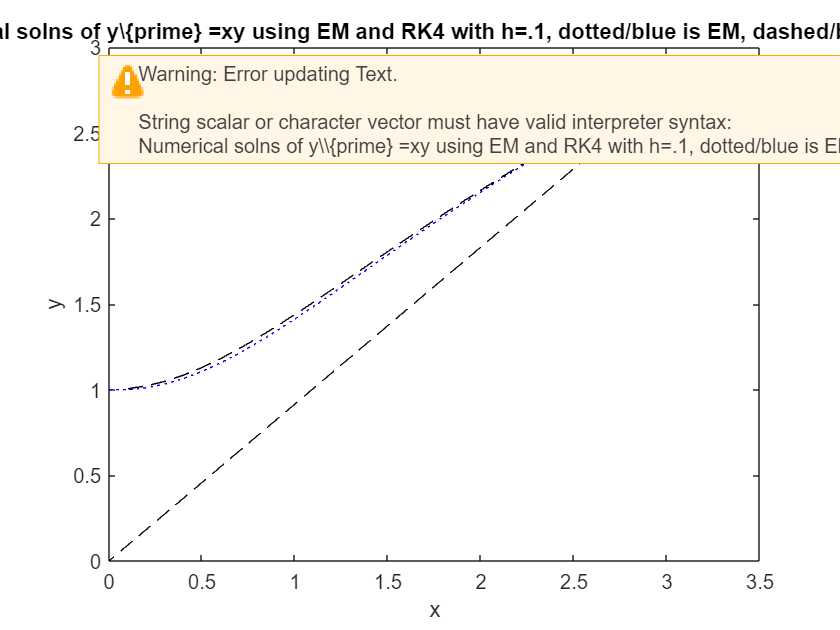

plot(x,y,'b:') %Now graphically compare Euler with RK4
hold on
plot(x1,y1,'k--')
xlabel('x')
ylabel('y')
title('Numerical solns of y\{prime} =xy using EM and RK4 with h=.1, dotted/blue is EM, dashed/black is RK4')
hold off

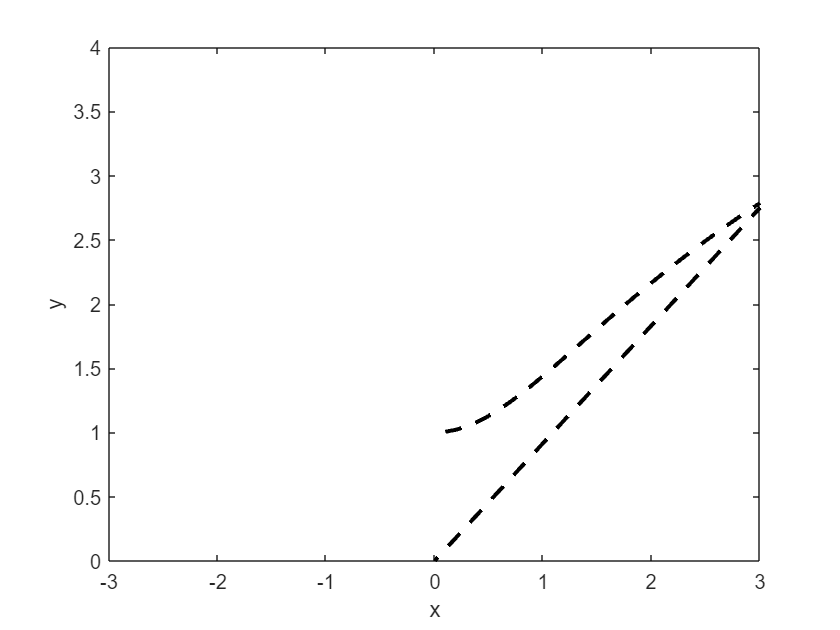


plot(x1,y1,'k--','LineWidth',2)
hold on
[X,Y]=meshgrid(-3:.3:3,0:.3:4);
DY=X.*Y; %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2);
quiver(X,Y,DX./DW,DY./DW,.4,'.');
xlabel('x');
ylabel('y');
axis([-3 3 0 4])
hold off

%End of Example 3.


## 5b



fprintf('Problem 5b \n')

Problem 5b 


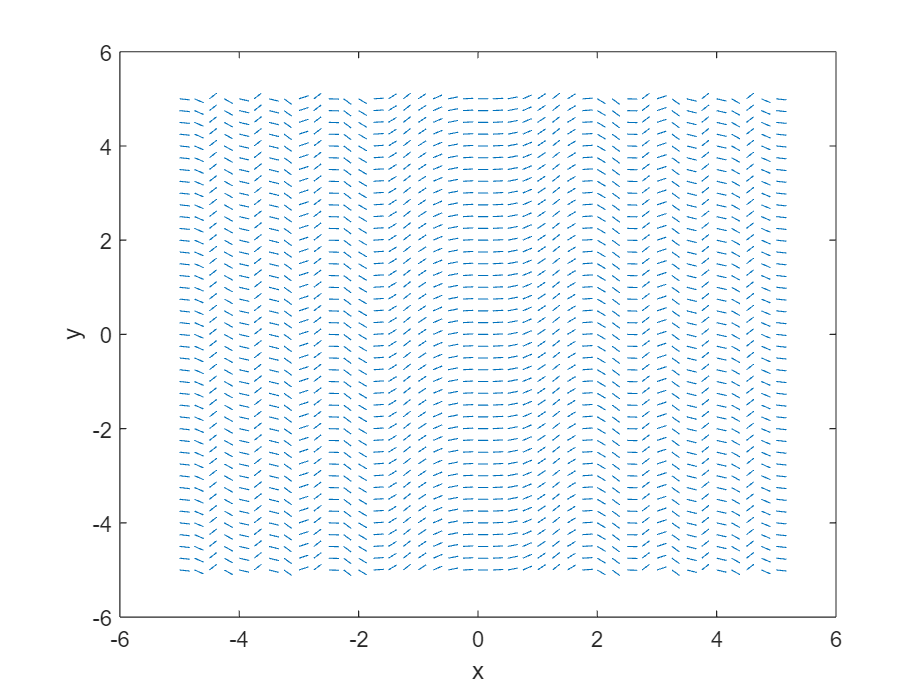

clear all;
[X,Y]=meshgrid(-5:.25:5,-5:.25:5); %Note the CAPITAL letters
DY=sin(X.^2); %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2); %the length of each vector
quiver(X,Y,DX./DW,DY./DW,.5,'.'); %plots normalized vectors
xlabel('x');
ylabel('y');

%% 5d
fprintf('Problem 5d \n')

Problem 5d 


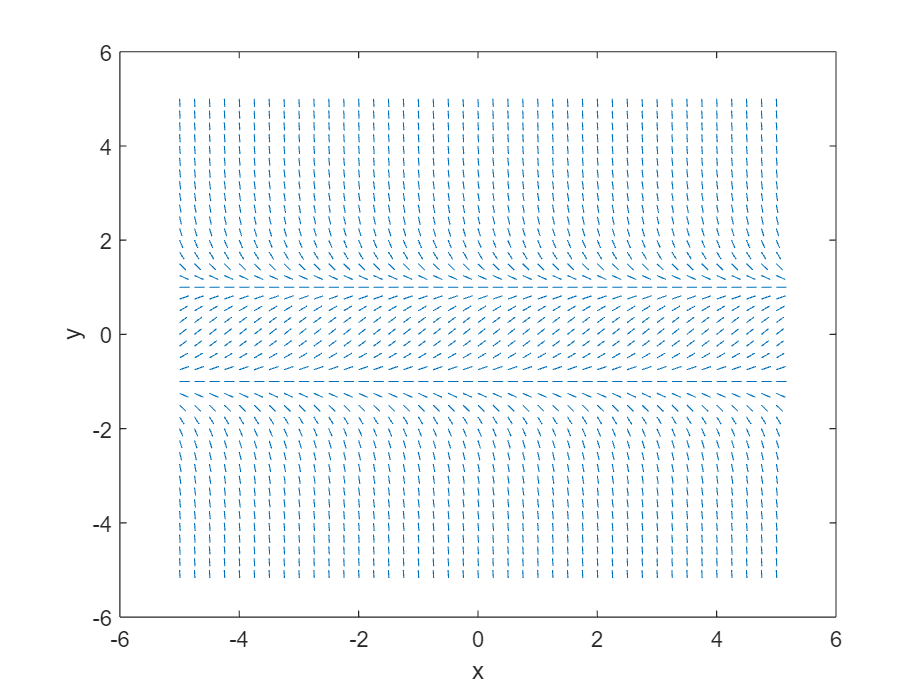

clear all;
[X,Y]=meshgrid(-5:.25:5,-5:.25:5); %Note the CAPITAL letters
DY=1-Y.^2; %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2); %the length of each vector
quiver(X,Y,DX./DW,DY./DW,.5,'.'); %plots normalized vectors
xlabel('x');
ylabel('y');

## 6b



fprintf('Problem 6b \n')

Problem 6b 


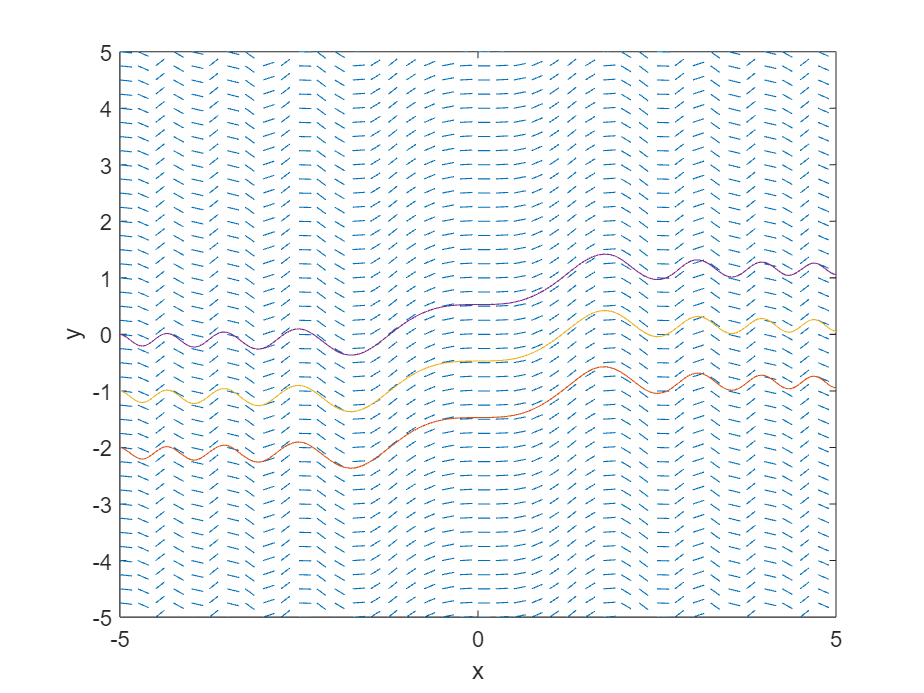

clear all;
[X,Y]=meshgrid(-5:.25:5,-5:.25:5); %Note the CAPITAL letters
DY=sin(X.^2); %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2); %the length of each vector
quiver(X,Y,DX./DW,DY./DW,.5,'.'); %plots normalized vectors
xlabel('x');
ylabel('y');

options=odeset('refine',10,'AbsTol',1e-15);

x0=-5; xf=5; y0=-2;
[x1,y1]=ode45(@Ch5bNumExample,[x0,xf],y0,options);

x0=-5; xf=5; y0=-1;
[x2,y2]=ode45(@Ch5bNumExample,[x0,xf],y0,options);

x0=-5; xf=5; y0=0;
[x3,y3]=ode45(@Ch5bNumExample,[x0,xf],y0,options);

hold on %keeps direction field plot open

axis([-5 5 -5 5])
plot(x1,y1)%superimpose solutions
plot(x2,y2)
plot(x3,y3)
hold off

## 6d



fprintf('Problem 6d \n')

Problem 6d 


clear all;
[X,Y]=meshgrid(-5:.25:5,-5:.25:5); %Note the CAPITAL letters
DY=1-Y.^2; %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2); %the length of each vector
quiver(X,Y,DX./DW,DY./DW,.5,'.'); %plots normalized vectors
xlabel('x');
ylabel('y');

options=odeset('refine',10,'AbsTol',1e-15);

x0=-2; xf=2; y0=0;
[x1,y1]=ode45(@Ch5dNumExample,[x0,xf],y0,options);

x0=-2; xf=2; y0=-2;
[x2,y2]=ode45(@Ch5dNumExample,[x0,xf],y0,options);

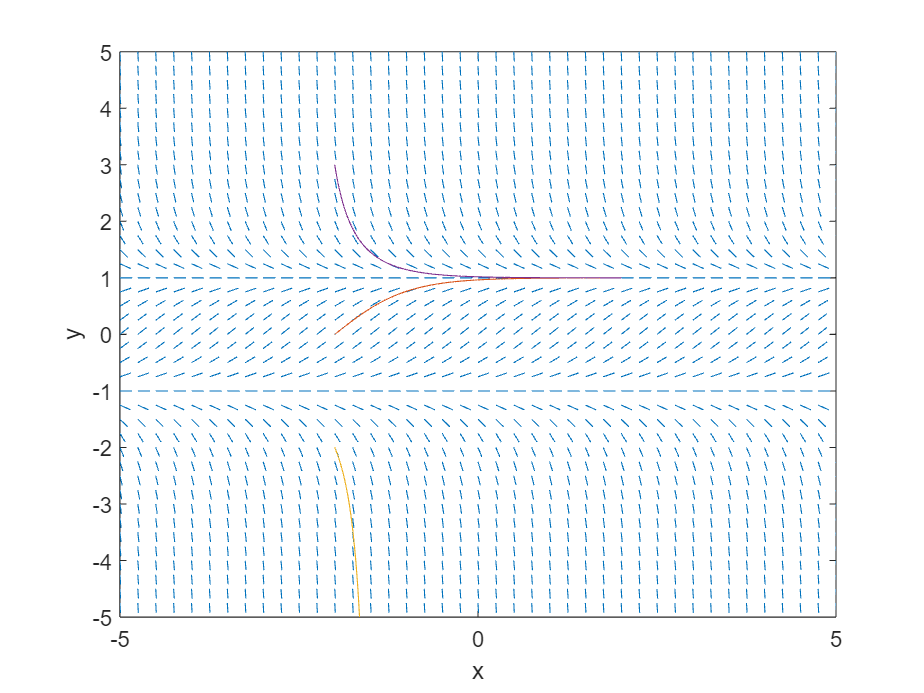


x0=-2; xf=2; y0=3;
[x3,y3]=ode45(@Ch5dNumExample,[x0,xf],y0,options);

hold on %keeps direction field plot open
%superimpose solutions
axis([-5 5 -5 5])
plot(x1,y1)
plot(x2,y2)
plot(x3,y3)
hold off

## 9

fprintf('Problem 9 \n')

Problem 9 


clear all;
close all;
x0=0; xf=5; y0=-1; h=.1;
[x,y]=Euler(@Ch9NumExample,[x0, xf],y0,h);
[x y]

ans =                          0                        -1
                       0.1                      -1.1
                       0.2                    -1.209
                       0.3                   -1.3259
                       0.4                  -1.44949
                       0.5                 -1.578439
                       0.6                -1.7112829
                       0.7               -1.84641119
                       0.8              -1.982052309
                       0.9             -2.1162575399


[x1,y1]=RK4(@Ch9NumExample,[x0 xf],y0,h);
[x1 y1]

ans =                        0.1         -1.10482895833333
                       0.2         -1.21859699057205
                       0.3         -1.34014080990134
                       0.4         -1.46817478566267
                       0.5          -1.6012780763498
                       0.6         -1.73788040937124
                       0.7         -1.87624636525849
                       0.8         -2.01445800903136
                       0.9         -2.15039569488953
                         1         -2.28171685211747



syms X Y(X)
eqn=diff(Y,X)==Y(X)+X.^2;
cond=Y(0)==-1;
ysol(X)=dsolve(eqn,cond);
ysol(X)

$$ans = {\mathrm{e}}^{X}-2\,X-X^{2}-2$$


x2=x0:h:xf; 
y2=exp(x)-2*x-x.^2-2 %this is the analytical solution

y2 =                         -1
         -1.10482908192435
         -1.21859724183983
           -1.340141192424
         -1.46817530235873
         -1.60127872929987
         -1.73788119960949
         -1.87624729252952
         -2.01445907150753
         -2.15039688884305


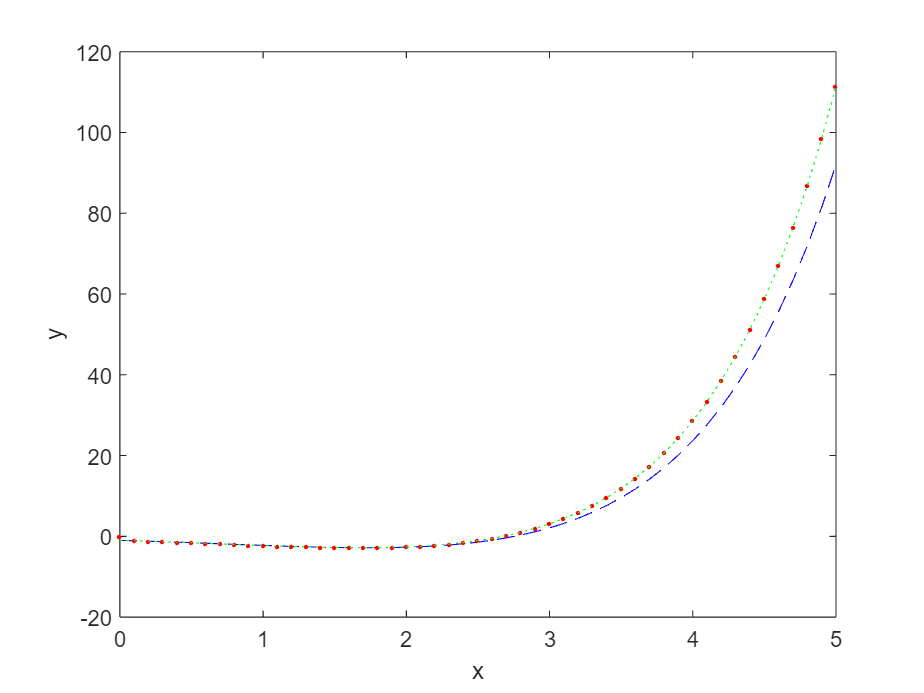

%[x2' y2']
plot(x,y,'b--') %Now graphically compare Euler with RK4
hold on
plot(x1,y1,'r.')
plot(x2,y2,'g:')
xlabel('x')
ylabel('y')
title('')
hold off

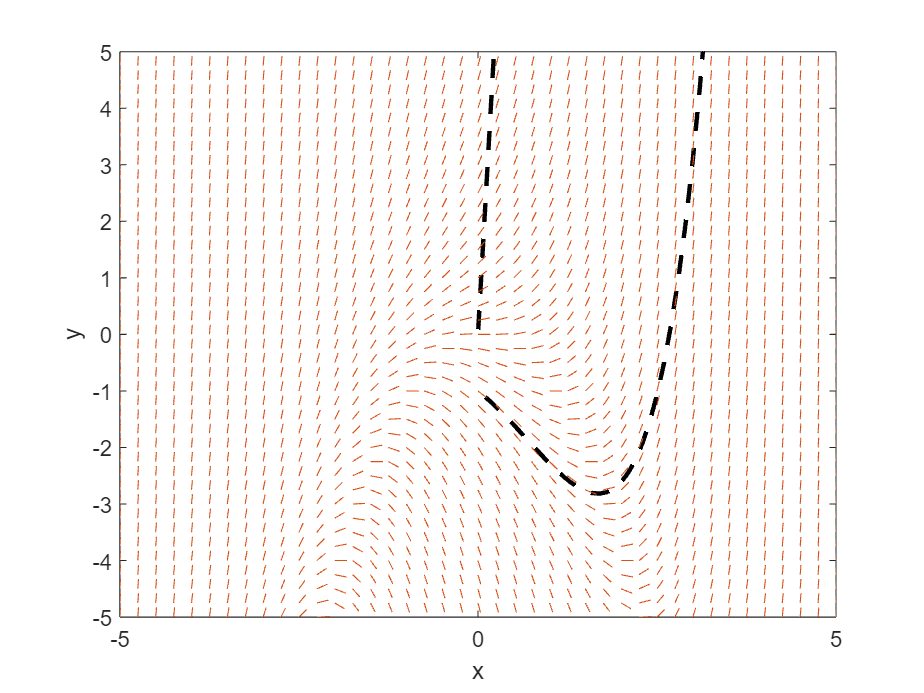


plot(x1,y1,'k--','LineWidth',2)
hold on
[X,Y]=meshgrid(-5:.25:5,-5:.25:5);
DY=Y+X.^2; %DY is rhs of original equation
DX=ones(size(DY));
DW=sqrt(DX.^2+DY.^2);
quiver(X,Y,DX./DW,DY./DW,.5,'.');
xlabel('x');
ylabel('y');
axis([-5 5 -5 5])
hold off


format longg
syms X Y(X)
eqn=diff(Y,X)==Y(X)+X.^2;
cond=Y(0)==-1;
ysol(X)=dsolve(eqn,cond);
ysol(X)

$$ans = {\mathrm{e}}^{X}-2\,X-X^{2}-2$$

[x1,y1]=Euler(@Ch9NumExample,[0,5],-1,0.1);
[x1, y1, double(ysol(x1))]

ans =                          0                        -1                        -1
                       0.1                      -1.1         -1.10482908192435
                       0.2                    -1.209         -1.21859724183983
                       0.3                   -1.3259           -1.340141192424
                       0.4                  -1.44949         -1.46817530235873
                       0.5                 -1.578439         -1.60127872929987
                       0.6                -1.7112829         -1.73788119960949
                       0.7               -1.84641119         -1.87624729252952
                       0.8              -1.982052309         -2.01445907150753
                       0.9             -2.1162575399         -2.15039688884305



[x2,y2]=RK4(@Ch9NumExample,[0,5],-1,0.1);
[x2, y2, double(ysol(x2))]

ans =                        0.1         -1.10482895833333         -1.10482908192435
                       0.2         -1.21859699057205         -1.21859724183983
                       0.3         -1.34014080990134           -1.340141192424
                       0.4         -1.46817478566267         -1.46817530235873
                       0.5          -1.6012780763498         -1.60127872929987
                       0.6         -1.73788040937124         -1.73788119960949
                       0.7         -1.87624636525849         -1.87624729252952
                       0.8         -2.01445800903136         -2.01445907150753
                       0.9         -2.15039569488953         -2.15039688884305
                         1         -2.28171685211747         -2.28171817154095



xeulerr4kanalyticalans=[0 -1 0 -1;
        0.1 -1.1 -1.10482895833333 -1.10482908192435;
        1 -2.24688329389 -2.28171685211747 -2.28171817154095;
        5 92.029938167665 111.412882112512 111.413159102577]

xeulerr4kanalyticalans =                          0                        -1                         0                        -1
                       0.1                      -1.1         -1.10482895833333         -1.10482908192435
                         1            -2.24688329389         -2.28171685211747         -2.28171817154095
                         5           92.029938167665          111.412882112512          111.413159102577


difference=[xeulerr4kanalyticalans(:,1) abs(xeulerr4kanalyticalans(:,2)-xeulerr4kanalyticalans(:,4)) abs(xeulerr4kanalyticalans(:,3)-xeulerr4kanalyticalans(:,4))]

difference =                          0                         0                         1
                       0.1       0.00482908192434994      1.23591020084746e-07
                         1        0.0348348776509502       1.3194234798064e-06
                         5           19.383220934912      0.000276990065003702



fprintf("The RK4 is more accurate than the Euler method from the analytical solution.")

The RK4 is more accurate than the Euler method from the analytical solution.